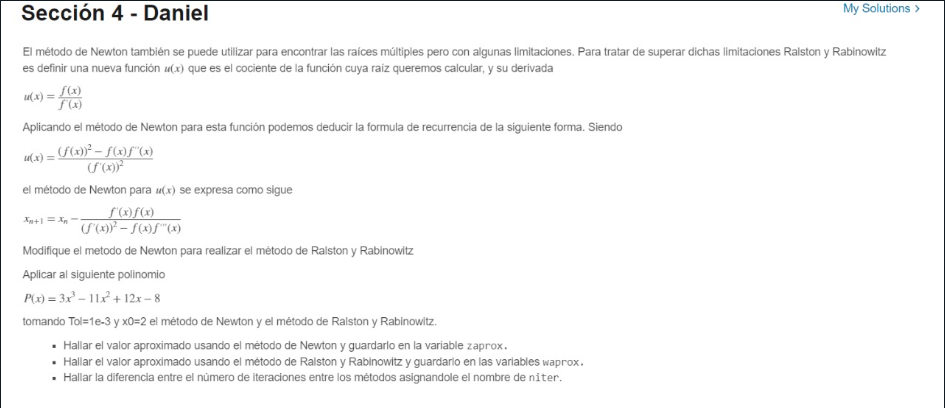

syms x

P(x) = 3*x^3 - 11*x^2+12*x-8;

tol = 1e-5;
x0 = 2;

zaprox = m_newton_rhapson(P,x0,tol);
new_iter = zaprox(end, 1)

new_iter = 6

zaprox

zaprox =          0    2.0000
    1.0000    3.0000
    2.0000    2.6296
    3.0000    2.5050
    4.0000    2.4907
    5.0000    2.4905
    6.0000    2.4905


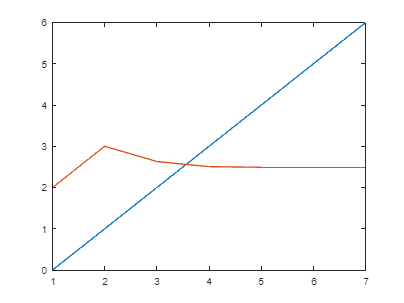

plot(zaprox)

zaprox = zaprox(end)

zaprox = 2.4905


waprox = m_newton_rhapson(P,x0,tol);
wat_iter = waprox(end)

wat_iter = 2.4905

waprox

waprox =          0    2.0000
    1.0000    3.0000
    2.0000    2.6296
    3.0000    2.5050
    4.0000    2.4907
    5.0000    2.4905
    6.0000    2.4905


plot(waprox)

waprox = waprox(end-1)  

waprox = 2.4905

niter = abs(zaprox - waprox)

niter = 2.8477e-08

function sol = m_newton_rhapson(f, x0, tol)
    syms x
    df=diff(f(x));
    dfu=matlabFunction(df);

    i = 0;

    sol = [i double(x0)];
    error=1;
    while error > tol
        x1 = x0-f(x0)/dfu(x0);
        error = double(abs(x1-x0)/abs(x1));
        x0 = double(x1);
        i = i + 1;
        sol = [sol; i x0];
    end
    
    %sol = [sol, i];
end
    
function sol = m_ralston_rabinowitz(f, x0, tol)
    syms x
    df=diff(f(x));
    df2 = diff(f(x),2);
    df3 = diff(f(x),3);
    
    dfu=matlabFunction(df);
    dfu2=matlabFunction(df);
    dfu3=matlabFunction(df);
    
    sol=[double(x0)];
    error=1;
    i = 0;
    while error>tol
    x1 = x0 - ( dfu(x0) * f(x0) ) / ( dfu(x0)^2 - f(x0)*dfu3(x0) );
        error=double(abs(x1-x0)/abs(x1));
        x0=double(x1);
        sol = [sol,x0];
        i = i + 1;
    end
    
    sol = [sol, i];
end